# **Marginal Analyses:** *A Guide*

The code in this live-script references functions contained in `analyze.marg`. Click **Run **to run the full script, or advance a single section at a time by clicking the button at the top of each section after setting the parameters as desired.

  % Click here to run analyses

Many of the population-level analyses that are described in assessments of neurophysiological spiking population dynamics seek to interpret not necessarily the mean firing rate, which indeed co-varies most strongly with specific elements of behavior, but rather, the unaccounted **variance **in underlying processes (sometimes referred to as *factors*), which might otherwise be better explained when viewed in covariance of overall population "dispersion" under certain task-specific conditions. This script tries to walk through that process in a sensible way.

### Initialize `marg` Data

Click **Initialize** to run the current section, initializing the main data table by excluding unwanted grouping categories (e.g. trials where no pellet was present).

  % Click here to run current section

#### `Clear workspace & load data (if needed)`

clearvars -except T G
if exist('T','var')==0
   % note that `'rate_table_default_matfile'` is the smaller table
   % it does not necessarily contain all Alignments etc. (just to save time
   % on loading). It may be necessary to load the other, larger `'T.mat'`
   % file, which doesn't have _default.mat apprended on the end of the
   % filename.
   load(defaults.files('rate_table_default_matfile'),'T');
end

#### Reduce table to working subset, `M`

M = analyze.marg.get_subset(T);

# **Remove Relevant Marginalizations**

Click **Marginalize **to run the current section, creating a data table of mean-subtracted trial rates that corresponds to trials with zero cross-trial average according to the groupings in `marginalizations`.

  % Click here to run current section

### Subtract group means in a principled way

We expect there to be large, striking differences in the observed neurophsyiological spiking time-series, with this being unsurprising for the following marginalizations: 

- `Group `(we expect a difference between *Ischemic* vs. *Intact *rats)

- `Rat` (we expect a *random *within-rat difference simply due to different combination of recording channels etc.)

- `Area `(we expect a difference on the basis of *Premotor *vs. *Motor *area)

- `ICMS `(motor representation, such as *Forelimb* vs. *Whiskers*)

- `Channel `(a huge difference for individual channels)

Note that it is likely that even mean-subtraction **across sessions **would have a substantial impact!

Therefore, we can optionally add the following marginalization filter:

- `BlockID` (recording session)

marginalizations = {'AnimalID','Area','Channel','Alignment','Outcome'};
outcome = 'Successful';
min_n_trials = 5;

#### Create marginalized dataset

S = analyze.marg.subtract_rat_means(M,marginalizations);
S = utils.filterByNTrials(S,min_n_trials,outcome); % Restrict subset to analyze

### View example of mean-subtracted rates

Click **Plot Rates **once you have selected the desired *Alignment *and *Outcome *parameters.

- **Plot Rates **will only run the current section.

  % This will change `small-s` (table) each time you click it

Set parameters:

- `animal`** : **Exemplar Animal to use in single-recording jPCA analysis/visualization

- `align_event` : Alignment event to use for single-recording jPCA analyses

- `save_fig`** : **Toggle checkbox on if you wish to automatically save the generated figure

- `show_pre_mean_subtraction`** : **Toggle checkbox on if you want to check pre-mean-subtraction data

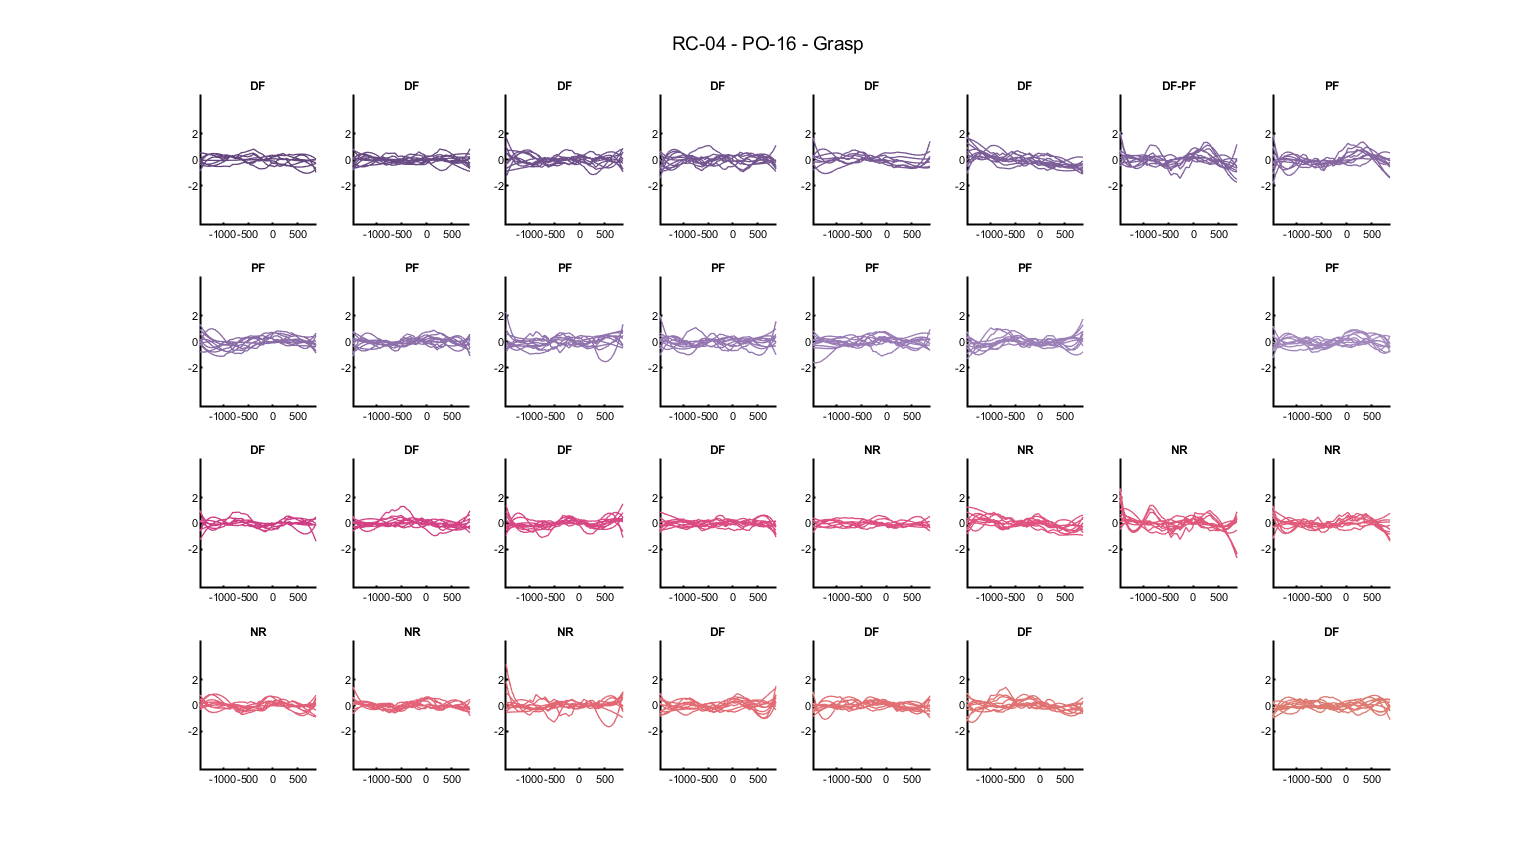

animal = 'RC-04';
align_event = 'Grasp';
save_fig = false; % Auto-saves the figure, if ticked
show_pre_mean_subtraction = false; % Show same data, prior to mean-subtraction

% % Survey of some that I've looked at % %
%   Intact group
% RC-14 - PO-05 - Grasp: same issue as some of Ischemia guys regarding
%       expansions and contractions while still having rotatory structure
% RC-18 - PO-17 - Grasp: looks good in jPCA on Plane-1
% RC-21 - PO-14 - Grasp: looks good in jPCA on Plane-1
% RC-43 - PO-24 - Grasp: looks good in jPCA on Plane-1
%
%   Ischemia group
% RC-02 - PO-17 - Grasp: not as strong jPCA structure on Plane-1
% RC-04 - PO-16 - Grasp: not as strong jPCA structure on Plane-1
% RC-05 - PO-08 - Grasp: not as strong jPCA structure on Plane-1
% RC-08 - PO-16 - Grasp: not as strong jPCA structure on Plane-1
% RC-26 - PO-19 - Grasp: definitely has separation between
%           success/unsuccesful in Plane-1, but has some elements of rotatory
%           structure combined with a lot of expansion/contraction elements.
% RC-30 - PO-16 (& others) - Grasp: has quite good jPCA structure on
%                               Plane-1. Note that on this day, he had many
%                               more successful trials included than
%                               unsuccessful trials, although the variance
%                               captured is lower in general for any of the
%                               visualized planes.

[fig_by_Channel,s] = analyze.rec.plot_rate(...

    utils.filterByNTrials(S,min_n_trials,outcome,'AnimalID',animal),... 
    align_event,outcome,save_fig,1);

This figure produces subplots for **all trials **of a **single Block**. Each subplot represents a different channel. The top two rows represent normalized spike rates on channels that are in Caudal Forelimb Area (CFA; rat M1 homolog) that is ipsilateral to the forelimb retrieving the pellet. The bottom two rows represent normalized spike rates on channels that are in Rostral Forelimb Area (RFA; rat PM homolog) contralateral to the forelimb retrieving the pellet. Time is represented on the x-axis in milliseconds. The bold text above each subplot indicates the approximate intracortical microstimulation (ICMS) co-registration from a mapping procedure done just prior to the insertion of the microwire arrays. It follows the key:

- **Distal Forelimb **(DF)

- **Proximal Forelimb **(PF)

- **Distal & Proximal Forelimb **(DF-PF)

- **No Response **(NR; 80 uA maximum current)

- **Other **(O; e.g. Trunk, Vibrissae, Mouth, etc.)

Verify that the mean-subtracted outcomes make sense; **the largest "modulated" component should be the task-aligned one. **Since we do not typically see "traditionally" coherent task-related fluctuations, particularly around the **0-ms** task alignment, it looks like we correctly subtracted the mean. You can see if there is a difference by toggling the check-box below.

if show_pre_mean_subtraction
    % Note that `M` is the pre-subtraction table
    [fig_by_Channel_orig] = analyze.rec.plot_rate(M(ismember(M.RowID,s.RowID),:),...
        align_event,outcome,save_fig,1); %#ok<UNRCH> 
end

# **Apply Population-Level Analysis**

Click **Make Struct **to create the formatted struct for analyzing the spike rates of trials from a single recording using the (modified) Churchland & Cunningham `jPCA` scripts.

  % Runs the current section to convert a single block into jPCA-formatted struct array

Using our marginalized dataset, we can now apply population-level analysis. A principled approach is detailed in (cite), which describes **jPCA, **a method that attempts to assess the strength of *rotatory dynamics *present under the assumption that the population dynamics are the result of factors governed in an oscillatory fashion, which is captured by a system of differential equations as:


$$\delta X=XM_{\textrm{skew}}$$


Where $M_{\textrm{skew}}$ is constrained to be skew-symmetric during the optimization procedure (a least-squares minimization). The recovered fit should then be compared to $M_{\textrm{best}}$, which is the optimal solution in the least-squares sense. If the fits are *comparable *(and that part can be nebulous; in general, it would seem that you want the top pairs of eigenvectors to capture 20-40% of the observed data variance as a seeming rule of thumb).

## Organize data for `jPCA` code

*Note that all code in *`analyze.jPCA`* is based on code kindly provided by John P. Cunningham & Mark Churchland; it has been changed slightly from the original format to accomodate some optional parameters for visualization purposes, and the documentation is changed to reflect notes as I was learning the material.*

#### We will use the (small-m) matrix that we inspected rates for above

if exist('s','var')==0
    error('Must run previous section prior to this one.')
end
area = "All";


		->	Table conversion for jPCA complete.


[Data,J,JID] = analyze.jPCA.convert_table(...
    s,align_event,area,...
    'Outcome',outcome);
if isempty(Data)
    error('No trials meet those criteria.');
end

### Verify `Data` exported as intended

Once the `Data` struct has been exported for `jPCA`, click **Check Data** to plot one of the exported trials, verifying that filtering/interpolating didn't do anything "weird."

  % Run current section (requires `Data` (formatted struct array))
if exist('Data','var')==0
    error('Must run previous section to extract `Data` first');
end

For jPCA, most parameters are set via the defaults and previously-initialized variables. The following parameters can be toggled as desired:

- `numPCs` : Total number of principal components to use for obtaining linearized dynamical system fit.

- `PCStem.PlotMeans`** : **Toggle to true in order to plot mean PC values for different conditions (outcomes). Only makes sense if using more than one outcome.

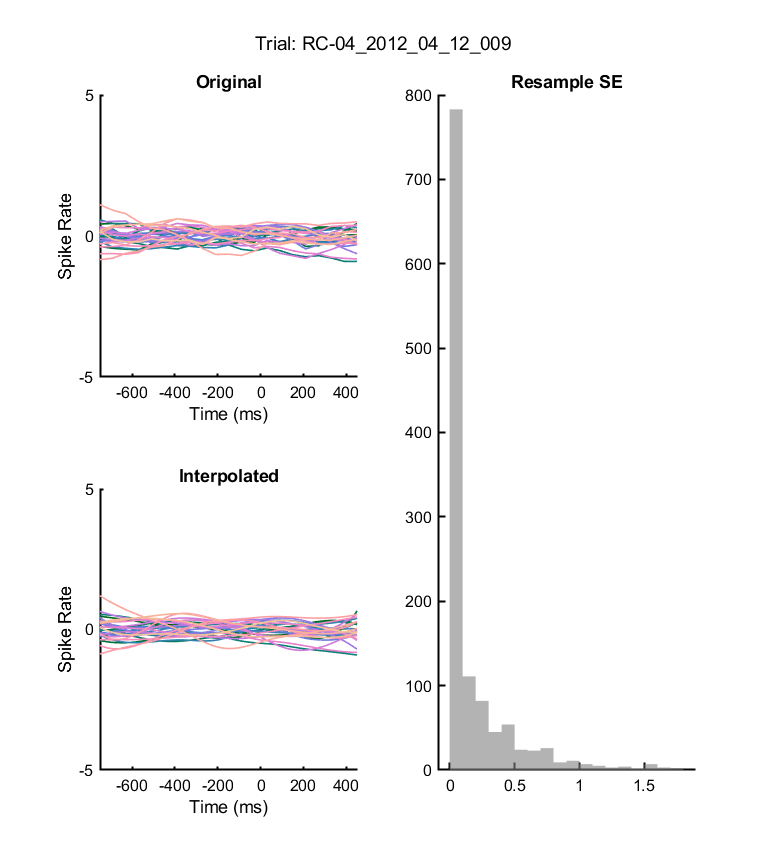

jPCA_params = defaults.jPCA('jpca_params');
jPCA_params.numPCs = 12;
jPCA_params.PCStem.PlotMeans = false; % Plot means if true, otherwise plot individual trials (PCs)
if exist('area','var')~=0
    jPCA_params.Area = area;
end
if exist('align_event','var')~=0


	BEGIN -> [RC-04::Grasp::Day-16 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.34+3.30i	-0.34-3.30i (26.92%)
		->	 0.04+2.68i	 0.04-2.68i (21.78%)
		->	 0.38+1.81i	 0.38-1.81i (15.00%)
		->	-0.14+1.42i	-0.14-1.42i (11.58%)
		->	-0.19+0.00i	 0.05+0.00i (0.94%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 3.21i	 0.00-3.21i (27.02%)
		->	-0.00 + 2.61i	-0.00-2.61i (21.96%)
		->	-0.00 + 1.82i	-0.00-1.82i (15.26%)
		->	-0.00 + 1.36i	-0.00-1.36i (11.45%)
		->	-0.00 + 0.06i	-0.00-0.06i (0.54%)


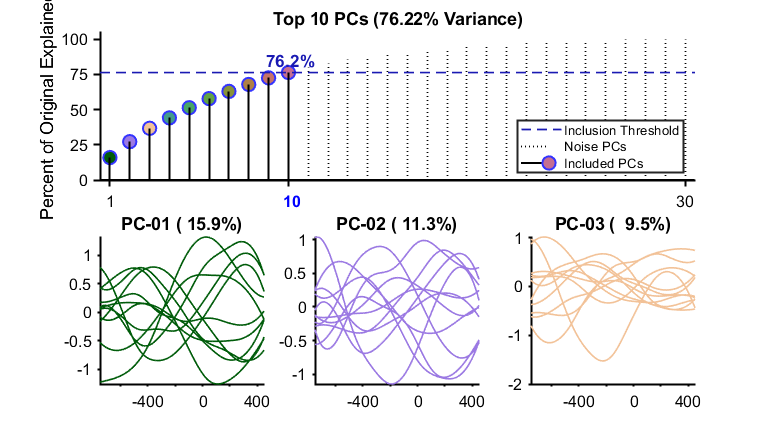

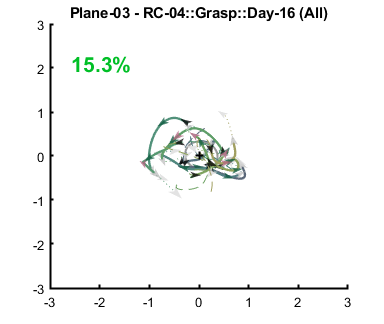

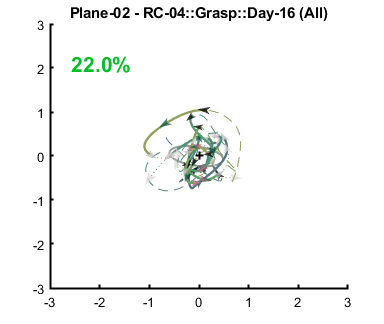

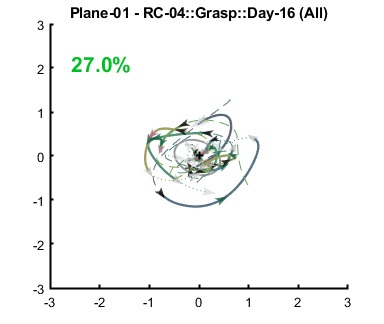



	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (   10  ) |         [ 76.22%]        |       38.27%
	 (Skew M) |  All  (   10  ) |         [ 76.22%]        |       20.86%
	 (Best M) | Top-2 (    eig) |         [ 26.92%]        |        2.60%
	 (Skew M) | Top-2 (    eig) |         [ 27.02%]        |        4.38% <<------
	->	[CIRC_CONFMEAN]: Requirements for confidence levels not met.


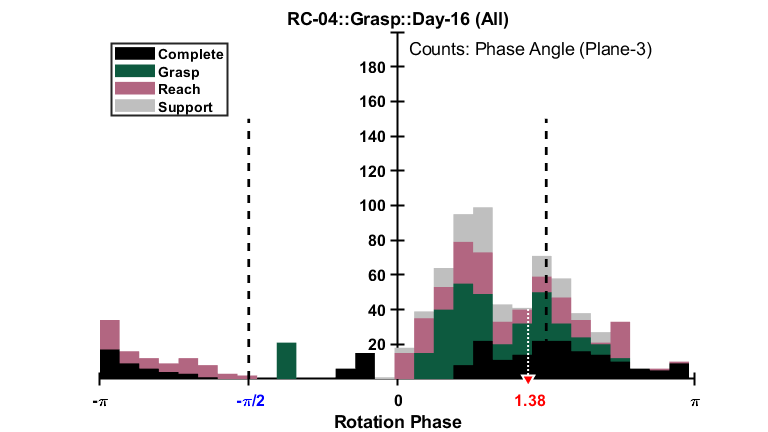

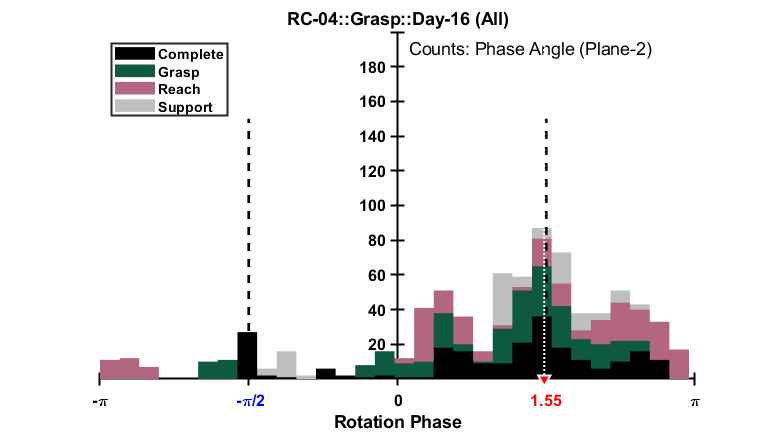

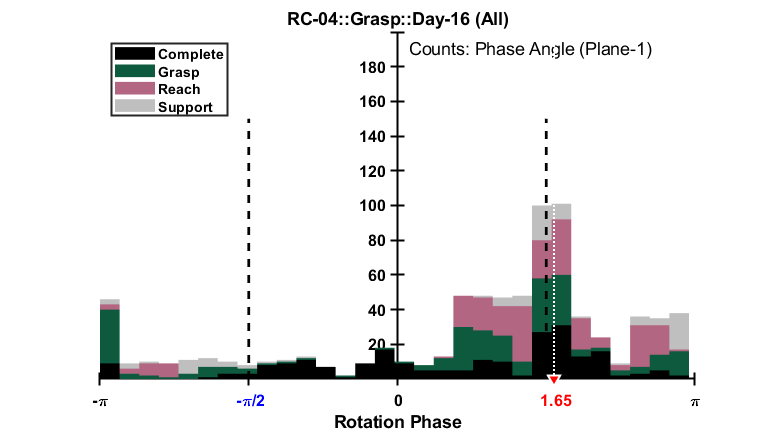


				[RC-04::Grasp::Day-16 (ALL)] <- END JPCA


    jPCA_params.Alignment = align_event;
end
if exist('animal','var')~=0
    jPCA_params.Animal = animal;
end
jPCA_params.Day = Data(1).PostOpDay;
fig = analyze.marg.plot_trial_to_double_check(Data,J);

In these panels, the top-left shows the "Original" spike rates (after an initial smoothing step, and whatever other processing has been applied, as shown in `J.Properties.UserData.Processing`. We need to visually inspect to make sure that the filtering and smoothing applied for the interpolation and export to `jPCA` to get the correct timescale to improve our nominal estimate of the derivative at each time-sample is **not causing the data to change drastically**. The distribution of errors (*right*) shows that, for a minority of the samples, there actually is a substantial change induced by this smoothing and interpolation step; however, the majority of the sample differences are very close to zero (and some of the error should be accounted for by non-exact matches of interpolated times compared to the "closest" original time, so that differences could be taken to begin with). 

## Recover `jPCA` projections and summary structure

With the recording block trial rate data in the appropriate `Data` array struct, click **Run jPCA** to recover the single-trial Projections and skew-symmetric projection matrix that best fits the linearized dynamical system.

  % Run current section (requires `Data` (formatted struct array))

This part actually recovers the jPCA projections for a single trial, and depending on the configured `jPCA_params` values, displays the rosettes, phase difference histograms, and some printouts such as the eigenvalues and the amount of data explained.

[Projection,Summary] = analyze.jPCA.jPCA(Data,jPCA_params);

**Top: **The panel shows the selected **jPCA plane**, which is spanned by a pair of basis vectors in the linear mapping of the data such that it is best fit to its own (time) derivative. The least-squares minimization procedure that recovers this matrix is constrained such that the algorithm must recover a skew-symmetric transformation matrix, which by definition should have pairs of complex-conjugate eigenvectors indicative of a "rotatory subspace" within the neuronal population time-series dynamics. Ideally, each "rosette" arrow (an individual trial)

**Bottom: **The distribution of phase angle differences between the position in jPCA-plane-space and the corresponding "velocity" of the neural trajectory at that position in jPCA-plane-space. A distribution centered about pi or -pi indicates an offset of 90 degrees between the two phase angles indicates "perfect" rotatory structure (e.g. circles) within the subspace.

# Export jPCs in multiple alignments

To perform a statistical analysis on the strength of rotatory subspaces captured using the `jPCA` method, so that we can assess trends across days (i.e. during recovery from focal ischemia), we want to export all the data in a batch as a big table, where each row quantifies the rotatory strength of a particular plane during a single trial in some alignment condition. The row should also indicate how much of the data is represented by this plane, and how accurately the projection matrix was able to linearize the dynamical system.

Click **Export all jPCA **to run the batch export, making sure that the checkbox is clicked (toggling it to false is the default so that clicking **Run **at the top doesn't accidentally start the batch export, which can take a few minutes depending on settings).

  % Run the current section

#### Execute a "batch" run to put the top-3 jPCs for each recording into Table format

*Note that jPC estimation is performed separately for each Alignment; therefore, the jPCs present during ****Reach ****may not reflect those present during ****Grasp****. For estimating the number of PCs, in this case we always use the largest even value that is less than the total number of channels present in the data.*

if true
    if exist('min_n_trials','var')==0
        min_n_trials = 5; % Minimum default
    end
    D = analyze.jPCA.multi_jPCA(S); % Should take ~ 1.5 minutes

#### Remove outliers that have less than 6 linearly independent data sources

This indicates that common noise across all channels is a dominating factor in the signals (and is rare; only two recordings need to be removed in this way).

%     D((D.AnimalID=="RC-21") & ismember(D.PostOpDay,[30,31]),:) = []; % Remove RC-21 Day 30 & Day 31
%     E = analyze.jPCA.export_table(D);
end


		->	Table conversion for jPCA complete.

	BEGIN -> [RC-05::Reach::Day-03 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 4.64+6.58i	 4.64-6.58i (29.14%)
		->	 0.90+5.22i	 0.90-5.22i (19.17%)
		->	-4.14+0.93i	-4.14-0.93i (15.36%)
		->	 1.26+3.96i	 1.26-3.96i (15.02%)
		->	-1.92+3.51i	-1.92-3.51i (14.48%)
		->	-0.24+1.78i	-0.24-1.78i (6.49%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 9.07i	-0.00-9.07i (31.75%)
		->	-0.00 + 6.73i	-0.00-6.73i (23.55%)
		->	 0.00 + 4.96i	 0.00-4.96i (17.39%)
		->	 0.00 + 3.95i	 0.00-3.95i (13.83%)
		->	-0.00 + 2.90i	-0.00-2.90i (10.14%)
		->	 0.00 + 0.85i	 0.00-0.85i (2.99%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] |


	BEGIN -> [RC-08::Grasp::Day-05 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.29+4.20i	 0.29-4.20i (25.62%)
		->	 1.32+3.50i	 1.32-3.50i (22.71%)
		->	-0.24+3.03i	-0.24-3.03i (18.47%)
		->	-1.50+2.24i	-1.50-2.24i (16.40%)
		->	-0.91+1.64i	-0.91-1.64i (11.39%)
		->	-0.80+0.00i	-0.38+0.00i (3.57%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 6.02i	 0.00-6.02i (34.02%)
		->	-0.00 + 4.48i	-0.00-4.48i (25.33%)
		->	 0.00 + 3.35i	 0.00-3.35i (18.92%)
		->	-0.00 + 1.97i	-0.00-1.97i (11.16%)
		->	 0.00 + 1.20i	 0.00-1.20i (6.78%)
		->	-0.00 + 0.34i	-0.00-0.34i (1.94%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | -------


	BEGIN -> [RC-08::Grasp::Day-05 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 3.31+0.00i	 1.18+1.59i (44.92%)
		->	 1.18-1.59i	-1.79+0.00i (31.94%)
		->	-1.34+0.00i	 0.32+0.00i (14.10%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 2.16i	 0.00-2.16i (55.71%)
		->	 0.00 + 0.96i	 0.00-0.96i (24.78%)
		->	 0.00 + 0.41i	 0.00-0.41i (10.46%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 90.96%]        |       36.12%
	 (Skew M) |  All  (    6  ) |         [ 90.96%]   


	BEGIN -> [RC-08::Grasp::Day-05 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-2.82+1.11i	-2.82-1.11i (46.76%)
		->	-0.56+2.15i	-0.56-2.15i (34.23%)
		->	-1.58+0.00i	 0.02+0.00i (12.30%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 2.40i	 0.00-2.40i (50.20%)
		->	-0.00 + 1.18i	-0.00-1.18i (24.79%)
		->	-0.00 + 0.87i	-0.00-0.87i (18.30%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 93.29%]        |       48.09%
	 (Skew M) |  All  (    6  ) |         [ 93.29%]   


	BEGIN -> [RC-30::Reach::Day-08 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 1.47+2.54i	 1.47-2.54i (21.40%)
		->	 0.03+2.84i	 0.03-2.84i (20.70%)
		->	 2.55+0.00i	-0.26+2.33i (17.85%)
		->	-0.26-2.33i	 0.97+0.00i (12.07%)
		->	-0.24+0.89i	-0.24-0.89i (6.70%)
		->	-0.68+0.00i	 0.32+0.00i (3.62%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 3.55i	 0.00-3.55i (25.21%)
		->	 0.00 + 3.40i	 0.00-3.40i (24.10%)
		->	 0.00 + 2.37i	 0.00-2.37i (16.81%)
		->	-0.00 + 1.43i	-0.00-1.43i (10.14%)
		->	-0.00 + 0.58i	-0.00-0.58i (4.15%)
		->	-0.00 + 0.27i	-0.00-0.27i (1.94%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | --------


	BEGIN -> [RC-30::Reach::Day-08 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.41+1.77i	 0.41-1.77i (40.37%)
		->	 0.13+0.92i	 0.13-0.92i (20.56%)
		->	 0.90+0.00i	 0.02+0.00i (10.24%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 2.09i	 0.00-2.09i (41.65%)
		->	 0.00 + 1.21i	 0.00-1.21i (24.09%)
		->	 0.00 + 0.27i	 0.00-0.27i (5.43%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 71.17%]        |       12.83%
	 (Skew M) |  All  (    6  ) |         [ 71.17%]    


	BEGIN -> [RC-30::Reach::Day-08 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.31+2.30i	-0.31-2.30i (47.63%)
		->	 0.38+0.80i	 0.38-0.80i (18.13%)
		->	 0.63+0.00i	 0.18+0.00i (8.33%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 2.66i	 0.00-2.66i (50.13%)
		->	-0.00 + 1.15i	-0.00-1.15i (21.72%)
		->	-0.00 + 0.12i	-0.00-0.12i (2.24%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 74.09%]        |       19.21%
	 (Skew M) |  All  (    6  ) |         [ 74.09%]     


	BEGIN -> [RC-14::Reach::Day-09 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 1.45+12.74i	 1.45-12.74i (30.30%)
		->	-0.15+8.82i	-0.15-8.82i (20.86%)
		->	-8.44+0.00i	 8.35+0.00i (19.84%)
		->	 0.93+5.37i	 0.93-5.37i (12.88%)
		->	-2.12+4.61i	-2.12-4.61i (12.00%)
		->	 1.52+0.72i	 1.52-0.72i (3.99%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 +13.04i	-0.00-13.04i (35.36%)
		->	 0.00 + 9.76i	 0.00-9.76i (26.47%)
		->	-0.00 + 6.17i	-0.00-6.17i (16.74%)
		->	 0.00 + 4.46i	 0.00-4.46i (12.08%)
		->	 0.00 + 2.09i	 0.00-2.09i (5.66%)
		->	-0.00 + 1.31i	-0.00-1.31i (3.55%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ----


	BEGIN -> [RC-14::Grasp::Day-09 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 1.86+18.44i	 1.86-18.44i (34.46%)
		->	11.32+4.64i	11.32-4.64i (22.76%)
		->	 1.59+10.29i	 1.59-10.29i (19.37%)
		->	-2.48+4.99i	-2.48-4.99i (10.37%)
		->	 0.46+4.69i	 0.46-4.69i (8.77%)
		->	-2.29+0.14i	-2.29-0.14i (4.26%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 +20.77i	 0.00-20.77i (46.26%)
		->	 0.00 +10.53i	 0.00-10.53i (23.46%)
		->	-0.00 + 6.89i	-0.00-6.89i (15.33%)
		->	-0.00 + 3.82i	-0.00-3.82i (8.51%)
		->	 0.00 + 2.41i	 0.00-2.41i (5.38%)
		->	-0.00 + 0.47i	-0.00-0.47i (1.04%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ---


	BEGIN -> [RC-14::Grasp::Day-09 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-1.53+6.36i	-1.53-6.36i (40.46%)
		->	 0.64+6.05i	 0.64-6.05i (37.63%)
		->	 3.59+0.00i	-3.22+0.00i (21.06%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 5.84i	 0.00-5.84i (57.69%)
		->	-0.00 + 4.09i	-0.00-4.09i (40.43%)
		->	 0.00 + 0.10i	 0.00-0.10i (1.03%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 99.16%]        |      308.53%
	 (Skew M) |  All  (    6  ) |         [ 99.16%]    


	BEGIN -> [RC-14::Grasp::Day-09 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-5.98+0.00i	 2.87+2.46i (45.06%)
		->	 2.87-2.46i	-3.70+0.00i (34.54%)
		->	-0.87+2.03i	-0.87-2.03i (20.40%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 3.15i	 0.00-3.15i (70.93%)
		->	-0.00 + 1.19i	-0.00-1.19i (26.86%)
		->	-0.00 + 0.10i	-0.00-0.10i (2.21%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [100.00%]        |      414.11%
	 (Skew M) |  All  (    6  ) |         [100.00%]    


	BEGIN -> [RC-30::Reach::Day-09 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.20+7.22i	 0.20-7.22i (29.22%)
		->	-0.94+4.69i	-0.94-4.69i (19.36%)
		->	 2.02+3.71i	 2.02-3.71i (17.11%)
		->	-2.94+2.22i	-2.94-2.22i (14.93%)
		->	 0.46+2.97i	 0.46-2.97i (12.16%)
		->	 2.46+0.00i	 0.66+0.00i (6.32%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 7.37i	-0.00-7.37i (29.91%)
		->	-0.00 + 5.68i	-0.00-5.68i (23.04%)
		->	-0.00 + 4.77i	-0.00-4.77i (19.34%)
		->	 0.00 + 3.89i	 0.00-3.89i (15.79%)
		->	 0.00 + 1.90i	 0.00-1.90i (7.69%)
		->	 0.00 + 0.82i	 0.00-0.82i (3.32%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | -------


	BEGIN -> [RC-30::Reach::Day-09 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 1.04+4.33i	 1.04-4.33i (42.99%)
		->	-1.07+3.83i	-1.07-3.83i (38.38%)
		->	 2.35+0.00i	 0.06+0.00i (11.61%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 4.50i	 0.00-4.50i (48.37%)
		->	 0.00 + 3.75i	 0.00-3.75i (40.33%)
		->	-0.00 + 0.40i	-0.00-0.40i (4.28%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 92.98%]        |      100.59%
	 (Skew M) |  All  (    6  ) |         [ 92.98%]    


	BEGIN -> [RC-30::Reach::Day-09 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.24+5.68i	 0.24-5.68i (61.45%)
		->	 2.12+0.00i	 0.75+1.29i (19.55%)
		->	 0.75-1.29i	-0.85+0.00i (12.68%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 5.53i	 0.00-5.53i (73.17%)
		->	-0.00 + 1.45i	-0.00-1.45i (19.20%)
		->	-0.00 + 0.10i	-0.00-0.10i (1.31%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 93.68%]        |       94.76%
	 (Skew M) |  All  (    6  ) |         [ 93.68%]    


	BEGIN -> [RC-14::Reach::Day-11 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-11.21+9.40i	-11.21-9.40i (40.70%)
		->	-0.72+5.95i	-0.72-5.95i (16.67%)
		->	 0.12+5.03i	 0.12-5.03i (13.99%)
		->	-0.03+4.18i	-0.03-4.18i (11.62%)
		->	 1.02+3.40i	 1.02-3.40i (9.87%)
		->	-2.47+0.00i	 2.37+0.00i (6.73%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 +10.96i	-0.00-10.96i (35.09%)
		->	 0.00 + 6.12i	 0.00-6.12i (19.59%)
		->	-0.00 + 5.06i	-0.00-5.06i (16.19%)
		->	 0.00 + 4.38i	 0.00-4.38i (14.01%)
		->	 0.00 + 3.37i	 0.00-3.37i (10.79%)
		->	-0.00 + 1.22i	-0.00-1.22i (3.92%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ----


	BEGIN -> [RC-14::Grasp::Day-11 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.40+16.53i	-0.40-16.53i (38.40%)
		->	 4.67+4.44i	 4.67-4.44i (14.97%)
		->	 1.30+6.23i	 1.30-6.23i (14.77%)
		->	-0.41+5.66i	-0.41-5.66i (13.19%)
		->	-1.07+4.10i	-1.07-4.10i (9.83%)
		->	 4.23+0.00i	-3.20+0.00i (8.63%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 +16.08i	 0.00-16.08i (43.46%)
		->	 0.00 + 7.03i	 0.00-7.03i (19.01%)
		->	 0.00 + 6.12i	 0.00-6.12i (16.53%)
		->	-0.00 + 3.99i	-0.00-3.99i (10.78%)
		->	-0.00 + 2.66i	-0.00-2.66i (7.19%)
		->	-0.00 + 1.04i	-0.00-1.04i (2.82%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | -----


	BEGIN -> [RC-14::Reach::Day-11 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.70+5.01i	 0.70-5.01i (65.01%)
		->	 3.11+0.00i	-1.20+0.00i (27.65%)
		->	 0.64+0.00i	-0.01+0.00i (4.21%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 5.60i	 0.00-5.60i (83.65%)
		->	 0.00 + 0.81i	 0.00-0.81i (12.11%)
		->	-0.00 + 0.07i	-0.00-0.07i (1.10%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 96.87%]        |       61.54%
	 (Skew M) |  All  (    6  ) |         [ 96.87%]     


	BEGIN -> [RC-14::Grasp::Day-11 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.35+5.42i	-0.35-5.42i (60.50%)
		->	 1.03+1.74i	 1.03-1.74i (22.49%)
		->	-0.96+0.96i	-0.96-0.96i (15.11%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 5.91i	 0.00-5.91i (65.94%)
		->	-0.00 + 2.19i	-0.00-2.19i (24.48%)
		->	-0.00 + 0.69i	-0.00-0.69i (7.67%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 98.10%]        |      127.14%
	 (Skew M) |  All  (    6  ) |         [ 98.10%]    


	BEGIN -> [RC-14::Reach::Day-11 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 5.14+0.00i	 0.29+3.42i (50.65%)
		->	 0.29-3.42i	 1.70+1.24i (32.69%)
		->	 1.70-1.24i	 0.03+0.00i (12.59%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 4.79i	 0.00-4.79i (67.15%)
		->	 0.00 + 1.95i	 0.00-1.95i (27.35%)
		->	-0.00 + 0.10i	-0.00-0.10i (1.42%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 95.92%]        |       66.27%
	 (Skew M) |  All  (    6  ) |         [ 95.92%]    


	BEGIN -> [RC-14::Grasp::Day-11 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 2.63+5.00i	 2.63-5.00i (47.69%)
		->	-1.36+5.15i	-1.36-5.15i (44.96%)
		->	 0.69+0.38i	 0.69-0.38i (6.64%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 4.79i	 0.00-4.79i (57.82%)
		->	 0.00 + 3.00i	 0.00-3.00i (36.19%)
		->	-0.00 + 0.44i	-0.00-0.44i (5.28%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 99.29%]        |      403.14%
	 (Skew M) |  All  (    6  ) |         [ 99.29%]     


	BEGIN -> [RC-30::Grasp::Day-11 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-1.09+4.27i	-1.09-4.27i (27.80%)
		->	-0.73+3.12i	-0.73-3.12i (20.21%)
		->	 0.89+2.91i	 0.89-2.91i (19.17%)
		->	 1.89+0.00i	-1.43+0.23i (10.54%)
		->	-1.43-0.23i	-0.91+0.00i (7.45%)
		->	 0.89+0.00i	-0.43+0.00i (4.17%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 4.51i	 0.00-4.51i (32.26%)
		->	-0.00 + 3.30i	-0.00-3.30i (23.61%)
		->	 0.00 + 2.18i	 0.00-2.18i (15.57%)
		->	 0.00 + 1.41i	 0.00-1.41i (10.10%)
		->	 0.00 + 0.96i	 0.00-0.96i (6.84%)
		->	 0.00 + 0.13i	 0.00-0.13i (0.96%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | --------


	BEGIN -> [RC-30::Grasp::Day-11 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-1.50+1.35i	-1.50-1.35i (45.76%)
		->	-0.50+0.88i	-0.50-0.88i (22.80%)
		->	 0.61+0.00i	-0.52+0.00i (12.81%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 1.61i	 0.00-1.61i (46.87%)
		->	 0.00 + 0.91i	 0.00-0.91i (26.54%)
		->	-0.00 + 0.27i	-0.00-0.27i (7.96%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 81.37%]        |       13.79%
	 (Skew M) |  All  (    6  ) |         [ 81.37%]    


	BEGIN -> [RC-30::Grasp::Day-11 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.74+3.66i	-0.74-3.66i (56.78%)
		->	 0.45+1.32i	 0.45-1.32i (21.27%)
		->	 1.09+0.00i	-0.09+0.00i (9.03%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 3.71i	-0.00-3.71i (60.27%)
		->	-0.00 + 1.45i	-0.00-1.45i (23.57%)
		->	 0.00 + 0.20i	 0.00-0.20i (3.24%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 87.08%]        |       38.57%
	 (Skew M) |  All  (    6  ) |         [ 87.08%]     


	BEGIN -> [RC-08::Grasp::Day-12 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.51+6.75i	-0.51-6.75i (30.81%)
		->	-1.29+4.79i	-1.29-4.79i (22.58%)
		->	 0.56+3.26i	 0.56-3.26i (15.07%)
		->	-0.97+2.82i	-0.97-2.82i (13.56%)
		->	 1.69+2.05i	 1.69-2.05i (12.08%)
		->	-0.75+0.00i	 0.22+0.00i (2.21%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 7.30i	 0.00-7.30i (35.01%)
		->	 0.00 + 5.22i	 0.00-5.22i (25.04%)
		->	 0.00 + 3.22i	 0.00-3.22i (15.45%)
		->	 0.00 + 2.22i	 0.00-2.22i (10.66%)
		->	-0.00 + 1.87i	-0.00-1.87i (8.94%)
		->	 0.00 + 0.25i	 0.00-0.25i (1.21%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | -------


	BEGIN -> [RC-08::Grasp::Day-12 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.94+2.74i	 0.94-2.74i (45.44%)
		->	-2.13+0.19i	-2.13-0.19i (33.50%)
		->	 0.03+0.72i	 0.03-0.72i (11.23%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 3.52i	 0.00-3.52i (65.76%)
		->	 0.00 + 1.19i	 0.00-1.19i (22.17%)
		->	-0.00 + 0.12i	-0.00-0.12i (2.24%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 90.17%]        |       30.59%
	 (Skew M) |  All  (    6  ) |         [ 90.17%]    


	BEGIN -> [RC-08::Grasp::Day-12 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-1.19+2.40i	-1.19-2.40i (46.42%)
		->	 2.03+0.00i	-1.47+0.00i (30.27%)
		->	 1.25+0.00i	-0.51+0.00i (15.25%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 2.36i	-0.00-2.36i (65.34%)
		->	-0.00 + 0.93i	-0.00-0.93i (25.68%)
		->	-0.00 + 0.03i	-0.00-0.03i (0.92%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 91.94%]        |       39.48%
	 (Skew M) |  All  (    6  ) |         [ 91.94%]    


	BEGIN -> [RC-08::Grasp::Day-14 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-2.59+0.00i	-0.60+2.43i (22.75%)
		->	-0.60-2.43i	-1.48+1.06i (19.30%)
		->	-1.48-1.06i	-0.22+1.34i (14.21%)
		->	-0.22-1.34i	 0.90+0.94i (11.87%)
		->	 0.90-0.94i	 0.97+0.00i (10.13%)
		->	 0.25+0.70i	 0.25-0.70i (6.63%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 2.76i	-0.00-2.76i (28.31%)
		->	-0.00 + 2.09i	-0.00-2.09i (21.44%)
		->	 0.00 + 1.51i	 0.00-1.51i (15.52%)
		->	 0.00 + 1.04i	 0.00-1.04i (10.66%)
		->	-0.00 + 0.72i	-0.00-0.72i (7.43%)
		->	-0.00 + 0.15i	-0.00-0.15i (1.55%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | -------


	BEGIN -> [RC-08::Grasp::Day-14 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.83+1.21i	 0.83-1.21i (32.68%)
		->	 1.24+0.47i	 1.24-0.47i (29.53%)
		->	 0.10+0.78i	 0.10-0.78i (17.49%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 1.64i	 0.00-1.64i (41.39%)
		->	 0.00 + 1.12i	 0.00-1.12i (28.15%)
		->	-0.00 + 0.40i	-0.00-0.40i (10.17%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 79.71%]        |       13.71%
	 (Skew M) |  All  (    6  ) |         [ 79.71%]   


	BEGIN -> [RC-08::Grasp::Day-14 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-3.26+0.00i	-0.87+1.12i (40.36%)
		->	-0.87-1.12i	-1.10+0.00i (21.77%)
		->	-0.01+0.96i	-0.01-0.96i (16.60%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 1.40i	-0.00-1.40i (42.65%)
		->	-0.00 + 0.87i	-0.00-0.87i (26.40%)
		->	 0.00 + 0.32i	 0.00-0.32i (9.67%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 78.73%]        |       18.94%
	 (Skew M) |  All  (    6  ) |         [ 78.73%]    


	BEGIN -> [RC-02::Grasp::Day-17 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 1.04+5.90i	 1.04-5.90i (22.15%)
		->	-2.67+5.29i	-2.67-5.29i (21.90%)
		->	 0.87+4.56i	 0.87-4.56i (17.16%)
		->	 2.41+3.03i	 2.41-3.03i (14.30%)
		->	-0.95+3.40i	-0.95-3.40i (13.05%)
		->	-0.91+2.72i	-0.91-2.72i (10.59%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 6.18i	 0.00-6.18i (24.61%)
		->	-0.00 + 5.36i	-0.00-5.36i (21.34%)
		->	 0.00 + 4.95i	 0.00-4.95i (19.69%)
		->	 0.00 + 4.07i	 0.00-4.07i (16.21%)
		->	 0.00 + 2.71i	 0.00-2.71i (10.80%)
		->	 0.00 + 1.63i	 0.00-1.63i (6.48%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | -----


	BEGIN -> [RC-02::Grasp::Day-17 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 1.95+4.61i	 1.95-4.61i (65.24%)
		->	-1.63+0.00i	 0.02+1.13i (17.98%)
		->	 0.02-1.13i	-0.15+0.00i (8.37%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 5.11i	-0.00-5.11i (63.97%)
		->	 0.00 + 1.73i	 0.00-1.73i (21.62%)
		->	 0.00 + 0.48i	 0.00-0.48i (6.01%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 91.60%]        |       57.59%
	 (Skew M) |  All  (    6  ) |         [ 91.60%]     


	BEGIN -> [RC-04::Reach::Day-17 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.92+10.59i	-0.92-10.59i (25.65%)
		->	-8.45+0.00i	 1.63+8.08i (20.13%)
		->	 1.63-8.08i	 8.16+0.00i (19.79%)
		->	-1.34+6.49i	-1.34-6.49i (15.99%)
		->	 0.98+3.79i	 0.98-3.79i (9.44%)
		->	-3.00+1.88i	-3.00-1.88i (8.54%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 +13.94i	 0.00-13.94i (34.92%)
		->	 0.00 +10.93i	 0.00-10.93i (27.38%)
		->	 0.00 + 5.53i	 0.00-5.53i (13.86%)
		->	-0.00 + 4.82i	-0.00-4.82i (12.07%)
		->	-0.00 + 3.27i	-0.00-3.27i (8.19%)
		->	 0.00 + 1.24i	 0.00-1.24i (3.12%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ----


	BEGIN -> [RC-04::Grasp::Day-17 (ALL)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.10+19.34i	 0.10-19.34i (39.09%)
		->	-8.47+0.00i	 0.25+7.98i (16.62%)
		->	 0.25-7.98i	 6.41+3.05i (15.24%)
		->	 6.41-3.05i	 1.22+4.83i (12.21%)
		->	 1.22-4.83i	-1.00+4.16i (9.35%)
		->	-1.00-4.16i	-2.74+0.00i (7.09%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 +24.00i	-0.00-24.00i (50.09%)
		->	-0.00 + 7.46i	-0.00-7.46i (15.57%)
		->	-0.00 + 5.91i	-0.00-5.91i (12.33%)
		->	 0.00 + 5.01i	 0.00-5.01i (10.46%)
		->	 0.00 + 3.77i	 0.00-3.77i (7.87%)
		->	 0.00 + 1.57i	 0.00-1.57i (3.28%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | -----


	BEGIN -> [RC-04::Grasp::Day-17 (CFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	-0.15+5.56i	-0.15-5.56i (55.72%)
		->	 4.59+0.00i	 2.44+0.00i (35.20%)
		->	-0.75+0.00i	-0.29+0.00i (5.19%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	-0.00 + 6.46i	-0.00-6.46i (53.99%)
		->	-0.00 + 4.62i	-0.00-4.62i (38.55%)
		->	 0.00 + 0.43i	 0.00-0.43i (3.56%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 96.11%]        |       82.81%
	 (Skew M) |  All  (    6  ) |         [ 96.11%]     


	BEGIN -> [RC-04::Grasp::Day-17 (RFA)]
			----------------------------------
			Eigenvalues of best transformation
			----------------------------------
		->	 0.20+5.29i	 0.20-5.29i (44.87%)
		->	 3.65+0.00i	 0.88+2.79i (27.87%)
		->	 0.88-2.79i	 2.55+0.00i (23.21%)

			----------------------------------
			Eigenvalues of skew transformation
			----------------------------------
		->	 0.00 + 5.54i	 0.00-5.54i (55.65%)
		->	-0.00 + 3.17i	-0.00-3.17i (31.85%)
		->	-0.00 + 0.84i	-0.00-0.84i (8.45%)


	--------- | --------------- | ------------------------ | --------------------
	(Mapping) |      Dims       | [% Eigenspace Explained] | % Variance Explained
	--------- | --------------- | ------------------------ | --------------------
	 (Best M) |  All  (    6  ) |         [ 95.95%]        |      241.82%
	 (Skew M) |  All  (    6  ) |         [ 95.95%]    

Not enough input arguments.

Error in analyze.jPCA.multi_jPCA (line 59)
   if isstruct(min_n_trials)